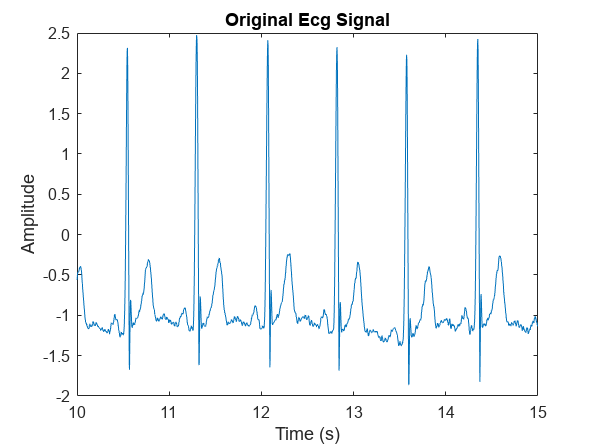

fileID = load("database\RECORDS");

file_name = int2str(fileID(16));
file_path = fullfile('database',file_name);
[signal,Fs,tm ]= rdsamp(file_path,1);

start_time = 10; 
end_time = 15;

start_idx = find(tm >= start_time, 1);
end_idx = find(tm >= end_time, 1);

selected_tm = tm(start_idx:end_idx);
selected_signal = signal(start_idx:end_idx);

% Plot the ECG data for the selected time range
figure;

plot(selected_tm, selected_signal);
title('Original Ecg Signal');
xlabel('Time (s)');
ylabel('Amplitude');

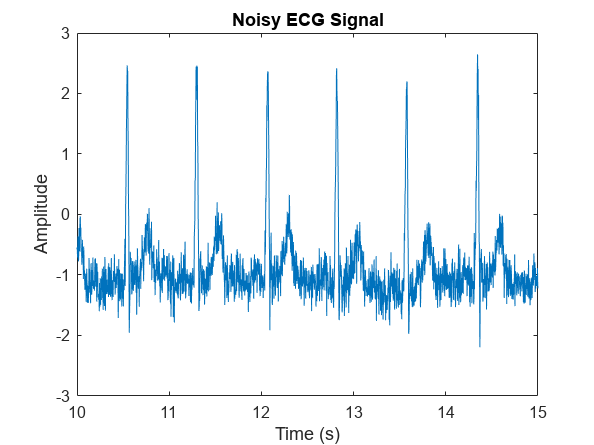




SNR_dB = 10;
noise = randn(size(signal));
scaling_factor = 10^(-SNR_dB / 20) * std(signal) / std(noise);


noisy_signal = signal + scaling_factor * noise;
selected_noisy_signal=noisy_signal(start_idx:end_idx);

% Plot the noisy signal
figure;
plot(selected_tm, selected_noisy_signal);
title('Noisy ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

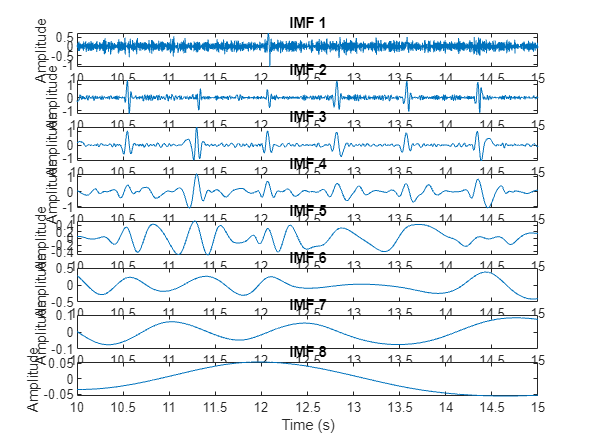




% Decompose the signal into IMFs using EMD
imfs = emd(selected_noisy_signal);

% Plot the IMFs
figure;
for i = 1:size(imfs, 2)
    subplot(size(imfs, 2), 1, i);
    plot(selected_tm, imfs(:, i));
    title(['IMF ' num2str(i)]);
    xlabel('Time (s)');
    ylabel('Amplitude');
end

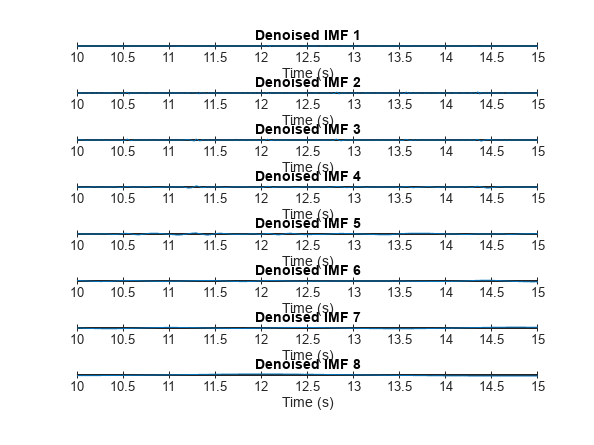



start_imf = 4; % Start from the 4th IMF
end_imf = size(imfs, 2);

residue = sum(imfs(:, start_imf:end_imf), 2);


% denoising parameters
level = 5;      
wavelet = 'db4'; 
threshold = 's'; 

%denoised version of each IMF
denoised_imfs = zeros(size(imfs));

for i = 1:size(imfs, 2)
    denoised_imfs(:, i) = wdenoise(imfs(:, i), level, 'Wavelet', wavelet, 'DenoisingMethod', threshold);
end

% Plot the denoised IMFs
figure;
for i = 1:size(denoised_imfs, 2)
    subplot(size(denoised_imfs, 2), 1, i);
    plot(selected_tm, denoised_imfs(:, i));
    title(['Denoised IMF ' num2str(i)]);
    xlabel('Time (s)');
    ylabel('Amplitude');
end

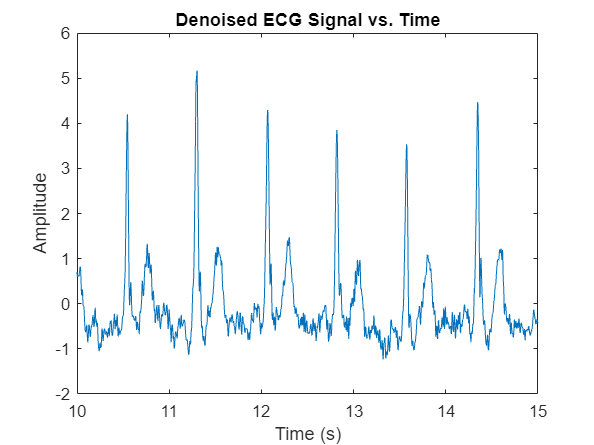


% Reconstruct the denoised signal 
denoised_signal = sum(denoised_imfs, 2) + residue;
figure;
plot(selected_tm,denoised_signal);
title('Denoised ECG Signal vs. Time');
xlabel('Time (s)');
ylabel('Amplitude');

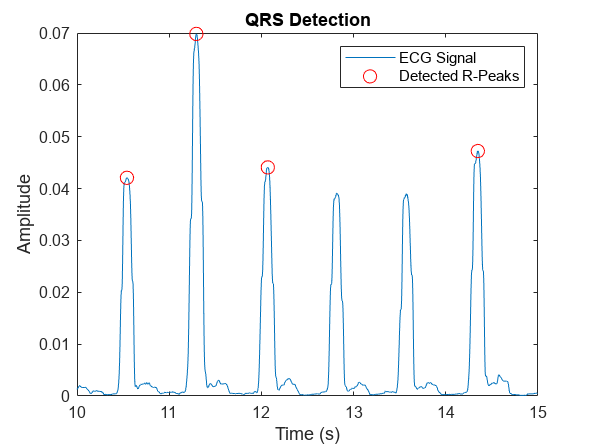




% Filter parameters
lowpass_cutoff = 20; 
highpass_cutoff = 0.5; 


denoised_signal = bandpass_filter(denoised_signal, lowpass_cutoff, highpass_cutoff, Fs);


ecg_diff = diff(denoised_signal);

ecg_squared = ecg_diff .^ 2;

window_size = round(0.12 * Fs); 
ecg_mwi = movmean(ecg_squared, window_size);

pt_selected_tm = selected_tm(1:length(ecg_mwi));

threshold = 0.6 * max(ecg_mwi);


r_peak_indices = find(ecg_mwi > threshold);

% Post-processing to keep only the highest peak within a range
range = round(0.2 * Fs); % Adjust the range as needed
final_r_peak_indices = [];
while ~isempty(r_peak_indices)
    peak_idx = r_peak_indices(1); 
  
    peaks_in_range = r_peak_indices(abs(r_peak_indices - peak_idx) <= range);
    [~, max_idx] = max(ecg_mwi(peaks_in_range)); 
    final_r_peak_indices = [final_r_peak_indices, peaks_in_range(max_idx)]; 
    r_peak_indices = setdiff(r_peak_indices, peaks_in_range); 
end

% Plot the ECG signal and detected R-peaks

figure;

plot(pt_selected_tm, ecg_mwi);
hold on;
plot(pt_selected_tm(final_r_peak_indices), ecg_mwi(final_r_peak_indices), 'ro', 'MarkerSize', 8);
title('QRS Detection');
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG Signal', 'Detected R-Peaks');

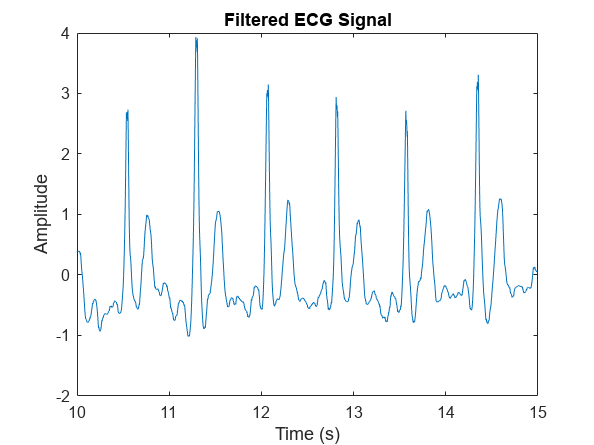


window_size = 10; 
threshold_factor = 0.5; 

filtered_ecg = ASMF(denoised_signal, window_size, threshold_factor);

figure;

plot(selected_tm,filtered_ecg);
title('Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

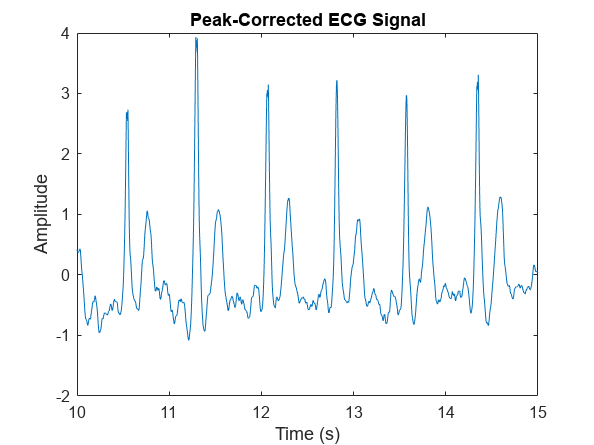


range = 10;


for nR = final_r_peak_indices 
    nR_start = max(1, nR - range);
    nR_end = min(length(denoised_signal), nR + range);
    denoised_signal(nR_start:nR_end) = filtered_ecg(nR_start:nR_end);
end

figure;
plot(selected_tm, denoised_signal);
title('Peak-Corrected ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');



NoisySNR = snr(selected_signal, selected_noisy_signal)

NoisySNR = -0.1591

DenoisedSNR = snr(selected_signal, denoised_signal)

DenoisedSNR = 2.4381


% Calculate Root Mean Square Error (RMSE)
rmse = sqrt(mean((denoised_signal - selected_signal).^2))

rmse = 0.9573

function filtered_signal = bandpass_filter(signal, lowpass_cutoff, highpass_cutoff, Fs)
    nyquist = Fs / 2;
    low = lowpass_cutoff / nyquist;
    high = highpass_cutoff / nyquist;
    [b, a] = butter(1, [high, low], 'bandpass');
    filtered_signal = filtfilt(b, a, signal);
end


function filtered_signal = ASMF(denoised_signal, window_size, threshold_factor)
    
    
    signal_length = length(denoised_signal);
    filtered_signal = denoised_signal;
    
    for n = 1:signal_length
        
        start_idx = max(1, n - floor(window_size / 2));
        end_idx = min(signal_length, n + floor(window_size / 2));
        
       
        window_samples = denoised_signal(start_idx:end_idx);
        window_mean = mean(window_samples);
        window_std = std(window_samples);

        threshold = threshold_factor * window_std;
        
        
        if abs(denoised_signal(n) - window_mean) > threshold
           
            filtered_signal(n) = window_mean;
        end
    end
end





